# MATLAB Deep Learning Toolbox

## MATLAB's  Deep Learning Toolbox

To use MATLAB's neural network software, we need to download the [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html#net). The documentation for the shallow neural network can be found on this page, but we will go over training the same neural network using their functions.

### Load the breast cancer image classification dataset

Let's load the breast cancer image classification dataset. The MATLAB built-in functions process datasets where the features/target variables span the rows, while the observations span the columns.

clear all; rng(2);
load cancer_dataset.mat

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

% Transpose all datasets
Xtrain = Xtrain'; Ytrain = Ytrain'; Xtest = Xtest'; Ytest = Ytest';

### Setting the shallow neural network architecture

Next, let's specify the neural network architecture for a shallow neural network. This can be done using the `feedforwardnet` function, which returns a structure consisting of the network values as fields.

Note that as a default, MATLAB uses the** Levenberg-Marquardt** algorithm, another optimization algorithm that tunes the model parameters to minimize the cost function. If you wanted to specify the optimization function, you can do so as the second argument in the `feedforwardnet` function. 

numOfActivationNodes = 2;         % 1 hidden layer with 2 activation nodes
optimizationFnc      = 'traingd'; % Gradient descent optimization algorithm
net                  = feedforwardnet(numOfActivationNodes, optimizationFnc)

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConne

### View the network structure with MATLAB's GUI

Let's view the network structure `net` using the `view` function, which utilizes MATLAB's GUI. 

view(net)

The popup screen should show you the following information:

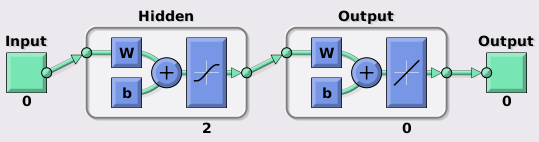

The numbers beneath each panel denotes the number of features (for the input/output) or the number of nodes in the network. Because we have not fitted the data using a training or testing set, the numbers below the input/output in the figure above are shown as 0. Note that this diagram is similar to the one we've been using to depict the network structure:

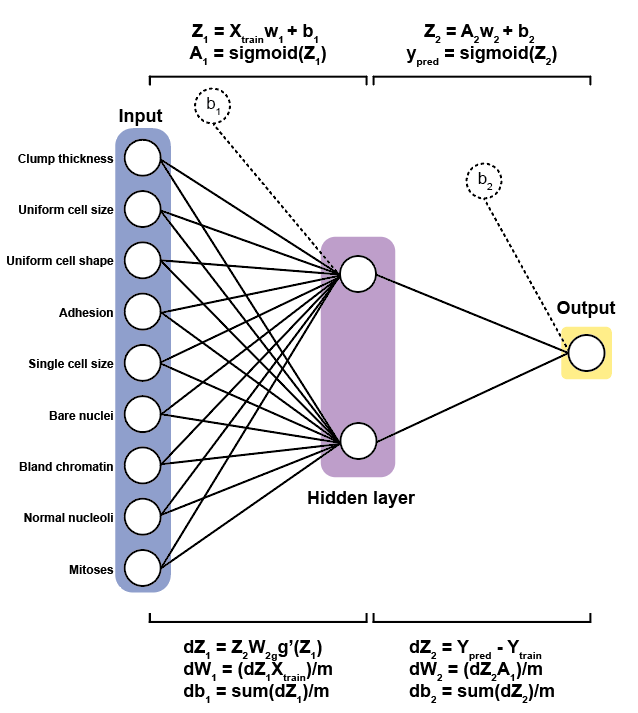

However, one main difference between the algorithm we wrote, and MATLAB's algorithm is that MATLAB only performs a final linear combination from the hidden to the output layer, while we have been re-transforming the linear combination to probabilities using another `Sigmoid` activation function. 

### Setting up the network hyperparameters

Most of the hyperparameters can be modified by setting the fields in the `net` structure. We won't go over each individual hyperparameter here (the documentation to modify some training parameters can be found in this [link](https://www.mathworks.com/help/deeplearning/ref/traingda.html)), but we'll some of the more important ones.

#### Validation sets

To divide the data for training, validation, and testing, we can specifying some fields in the `net` structure we made from the `fitnet` function.

net.divideParam.trainRatio = 0.6; % Training set size
net.divideParam.testRatio  = 0.2; % Test set size
net.divideParam.valRatio   = 0.2; % Cross validation set size

During the training phase, if you input the entire dataset, it automatically splits the dataset into three groups: 60% training, 20% testing (holdout), and an additional 20% for cross validation accuracy determinination. 

#### Loss functions

By default, the loss function is specified as the mean squared error. We'll use the MATLAB default features, but if we wanted to compute classification errors using the cross entropy loss function, we need to specify the `crossentropy` function using the following syntax:

%net.performFcn             = 'crossentropy';
net.performFcn             = 'mse';

#### Epochs

The number of epochs can be specified by setting the `net.trainParam.epochs` parameter. While MATLAB performs 1000 epochs by default, we'll set it to 10000 just to ensure we'll fully train the model. 

net.trainParam.epochs      = 10000;

MATLAB automatically performs **early stopping - **it stops training the model when the model error increases during an epoch. This is a nice feature to implement that helps the model avoid overfitting. 

### Training the shallow neural network

Let's now train the shallow neural network using the `train` function, which will also show the MATLAB GUI while the model is training. An example of the GUI is shown below.

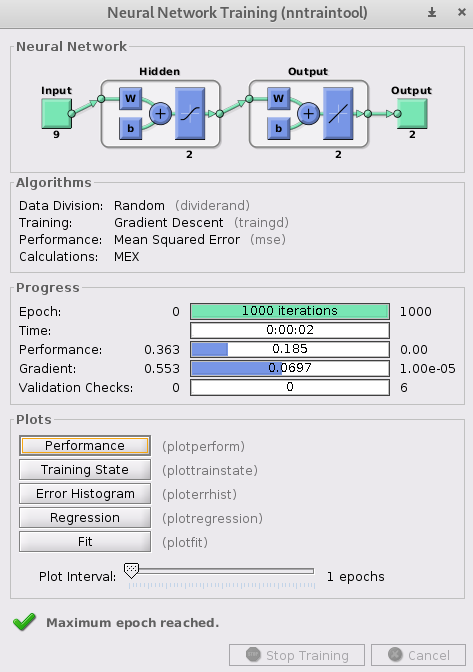

`train` takes in the network architecture we specified (`net)`, the `input` data, and the target labels `outputs`, and outputs the trained neural network (`trainedNet)`, as well as the computed metrics (`trainingRecord)`. 

[trainedNet, trainingRecord] = train(net, Xtrain, Ytrain)

trainedNet =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 23
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      in

trainingRecord = struct with fields:
        trainFcn: 'traingd'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×335 double]
          valInd: [1×112 double]
         testInd: [1×112 double]
            stop: 'Maximum epoch reached.'
      num_epochs: 10000
       trainMask: {[1×559 double]}
         valMask: {[1×559 double]}
        testMask: {[1×559 double]}
      best_epoch: 10000
            goal: 0
          states: {1×7 cell}
           epoch: [1×10001 double]
            time: [1×10001 double]
            perf: [1×10001 double]
           vperf: [1×10001 double]
           tperf: [1×10001 double]
        gradient: [1×10001 double]
        val_fail: [1×10001 double]
       best_perf: 0.0225
      best_vperf: 0.0503
      best_tperf: 0.0269


### Computing model predictions and evaluating model performance

First, we'll compute our predictions using the test dataset. The trained neural network `trainedNet` also acts as function to compute predictions. We can use the following syntax to compute the predicted Y values from the test set.

ypred = trainedNet(Xtest)

ypred =    -0.0992    0.0179    1.0105    0.3424    0.9180    1.0113    0.2061    0.0652    1.0113    1.0152    0.0065    0.0188    1.0073    0.0097    0.3791    0.9813    1.0125    0.0470   -0.0169    1.0152   -0.0345    0.0415    0.0387    0.9655    0.9908    0.9455    0.0925    0.9672    0.0022    0.0545    0.2487    0.9767    0.0020    0.9983    0.9659    0.0273   -0.1891    1.0109    0.9983    1.0125    0.0514    1.0080    0.9510    1.0073    1.0080    1.0031    0.8407    0.2494    1.0073    0.0340


From here we can use the methods we described previously to evaluate the model. However, we can also just use all of MATLAB's internal functions to compute the error rates. The following block of code will compute the model metrics using the trained model:

[~, trainRecordTest] = train(trainedNet, Xtest, Ytest)

trainRecordTest = struct with fields:
        trainFcn: 'traingd'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×84 double]
          valInd: [1×28 double]
         testInd: [1×28 double]
            stop: 'Maximum epoch reached.'
      num_epochs: 10000
       trainMask: {[1×140 double]}
         valMask: {[1×140 double]}
        testMask: {[1×140 double]}
      best_epoch: 10000
            goal: 0
          states: {1×7 cell}
           epoch: [1×10001 double]
            time: [1×10001 double]
            perf: [1×10001 double]
           vperf: [1×10001 double]
           tperf: [1×10001 double]
        gradient: [1×10001 double]
        val_fail: [1×10001 double]
       best_perf: 0.0040
      best_vperf: 0.0402
      best_tperf: 0.0393


Let's get the error rates from the `trainRecordTest` structure we just computed.

trainingAccuracy = 1 - trainRecordTest.best_perf
holdOutAccuracy  = 1 - trainRecordTest.best_tperf
holdOutAccuracy  = 1 - trainRecordTest.best_vperf

### Plotting model metrics 

#### Cost Curves

We can plot the cost curves we've generated previously using the `plotperf` function. Note that the error is in log-scale, unlike the plots we have computed previously. Additionally, it plots the training error, test error, and validation error as separate cost curves.

plotperf(trainRecordTest)

layers =   8x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 9 dimensions
     2   ''   Fully Connected         10 fully connected layer
     3   ''   Softmax                 softmax
     4   ''   Fully Connected         40 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Fully Connected         2 fully connected layer
     7   ''   Softmax                 softmax
     8   ''   Classification Output   crossentropyex

### Confusion matricies

Now plot a confusion matrix of the model holdout using the `confusionmat` and the `confusionchart` functions..

cm = confusionmat(round(ypred), Ytest);
figure; labels = {'Malignant', 'Benign'};
confusionchart(cm, labels)
title('Confusion matrix from 5-fold cross validation');
TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)
malignant_recall    = (TP) / (TP + FN)
benign_precision    = (TN) / (TN + FP)
benign_recall       = (TN) / (TN + FN)
average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

## Deep feed-forward neural networks and deep learning

Up until this point, we have only been dealing with a single hidden layer. What if we wanted to extend our neural network's capacity to handle $L$hidden layers to train a more non-linear model? 

We can generalize the approach we have used to construct the shallow neural network using the generalized forward and backward propagation algorithm, shown below. 

#### The general forward propagation algorithm

$Z^{\left\lbrack L\right\rbrack } =A^{\left\lbrack L-1\right\rbrack } w^{\left\lbrack L\right\rbrack } +{b\;}^{\left\lbrack L\right\rbrack }$. Note that $A^{\left\lbrack 1\right\rbrack } =X$.

$A^{\left\lbrack L\right\rbrack } =g^{\left\lbrack L\right\rbrack } \left(Z^{\left\lbrack L\right\rbrack } \right)$, where $g^{\left\lbrack L\right\rbrack }$ is a non-linear function of our choosing at an $L^{\textrm{th}}$ layer.

#### The general backward propagation algorithm

${\textrm{dZ}}^{\left\lbrack L\right\rbrack } ={\textrm{dA}}^{\left\lbrack L\right\rbrack } \cdot$$g^{\prime \left\lbrack L\right\rbrack } \left(Z^{\left\lbrack L\right\rbrack } \right)$, where ${\textrm{dA}}^{\left\lbrack \textrm{end}\right\rbrack } =Y_{\textrm{train}} -Y_{\textrm{pred}}$ and $g^{\prime \left\lbrack L\right\rbrack }$ is the derivative term for the activation function at layer $L$.


$${\textrm{dA}}^{\left\lbrack L-1\right\rbrack } =W^{\left\lbrack L\right\rbrack } {\textrm{dZ}}^{\left\lbrack L\right\rbrack }$$



$${\textrm{dW}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\left({{\textrm{dZ}}^{\left\lbrack L\right\rbrack } A}^{\left\lbrack L-1\right\rbrack } \right)$$



$${\mathrm{db}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\left({\mathrm{dZ}}^{\left\lbrack L\right\rbrack } \right)$$


A non-elegant way of doing this using `for loops` for each layer is shown in the `DNN.mlx` script provided. However, we'll mostly discuss how to construct a deep neural network using MATLAB's deep learning toolbox.

### Deep neural networks from the Deep Learning Toolbox

MATLAB has made it easy to construct deep neural networks by simply using the `trainNetwork` function. It takes in the datasets $X_{\textrm{train}}$ and $Y_{\textrm{train}}$, the network architecture as the third argument, and the hyperparameter specifications in the 4th argument. 

For a classification problem, the labels need to be transformed to a categorical data type:

Training on single GPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:00 |       33.45% |       61.43% |       0.6961 |       0.8796 |          0.0100 |


|      30 |          30 |       00:00:01 |       66.55% |       61.43% |       0.6392 |       0.6669 |          0.0100 |


|      50 |          50 |       00:00:01 |       66.55% |              |       0.6385 |              |          0.0100 |


|      60 |          60 |       00:00:01 |       66.55% |       61.43% |       0.6378 |       0.6736 |          0.0100 |


|      90 |          90 |       00:00:02 |       66.55% |       61.43% |       0.6373 |       0.6732 |          0.0100 |


|     100 |         100 |       00:00:02 |       66.55% |              |       0.6373 |              |          0.0100 |


|     120 |         120 |       00:00:02 |       66.55% |       61.43% |       0.6373 |       0.6726 |          0.0100 |


|     150 |         150 |       00:00:02 |       66.55% |       61.43% |       0.6373 |       0.6725 |          0.0100 |


|     180 |         180 |       00:00:03 |       66.55% |       61.43% |       0.6372 |       0.6724 |          0.0100 |


|     200 |         200 |       00:00:03 |       66.55% |              |       0.6356 |              |          0.0100 |


|     210 |         210 |       00:00:03 |       66.55% |       61.43% |       0.6022 |       0.6105 |          0.0100 |


|     240 |         240 |       00:00:04 |       98.03% |       97.86% |       0.0888 |       0.0873 |          0.0100 |


|     250 |         250 |       00:00:04 |       98.03% |              |       0.0818 |              |          0.0100 |


|     270 |         270 |       00:00:04 |       98.03% |       97.14% |       0.0754 |       0.1408 |          0.0100 |


|     300 |         300 |       00:00:04 |       98.03% |       97.14% |       0.0749 |       0.1753 |          0.0100 |


|     330 |         330 |       00:00:05 |       98.03% |       97.14% |       0.0747 |       0.1816 |          0.0100 |


|     350 |         350 |       00:00:05 |       98.03% |              |       0.0747 |              |          0.0100 |


|     360 |         360 |       00:00:05 |       98.03% |       97.14% |       0.0747 |       0.1858 |          0.0100 |


|     390 |         390 |       00:00:06 |       98.03% |       97.14% |       0.0746 |       0.1887 |          0.0100 |


|     400 |         400 |       00:00:06 |       98.03% |              |       0.0746 |              |          0.0100 |


|     420 |         420 |       00:00:06 |       98.03% |       97.14% |       0.0745 |       0.1910 |          0.0100 |


|     450 |         450 |       00:00:07 |       98.03% |       97.14% |       0.0745 |       0.1929 |          0.0100 |


|     480 |         480 |       00:00:07 |       98.03% |       97.14% |       0.0744 |       0.1946 |          0.0100 |


|     500 |         500 |       00:00:07 |       98.03% |       97.14% |       0.0744 |       0.1956 |          0.0100 |


|======================================================================================================================|


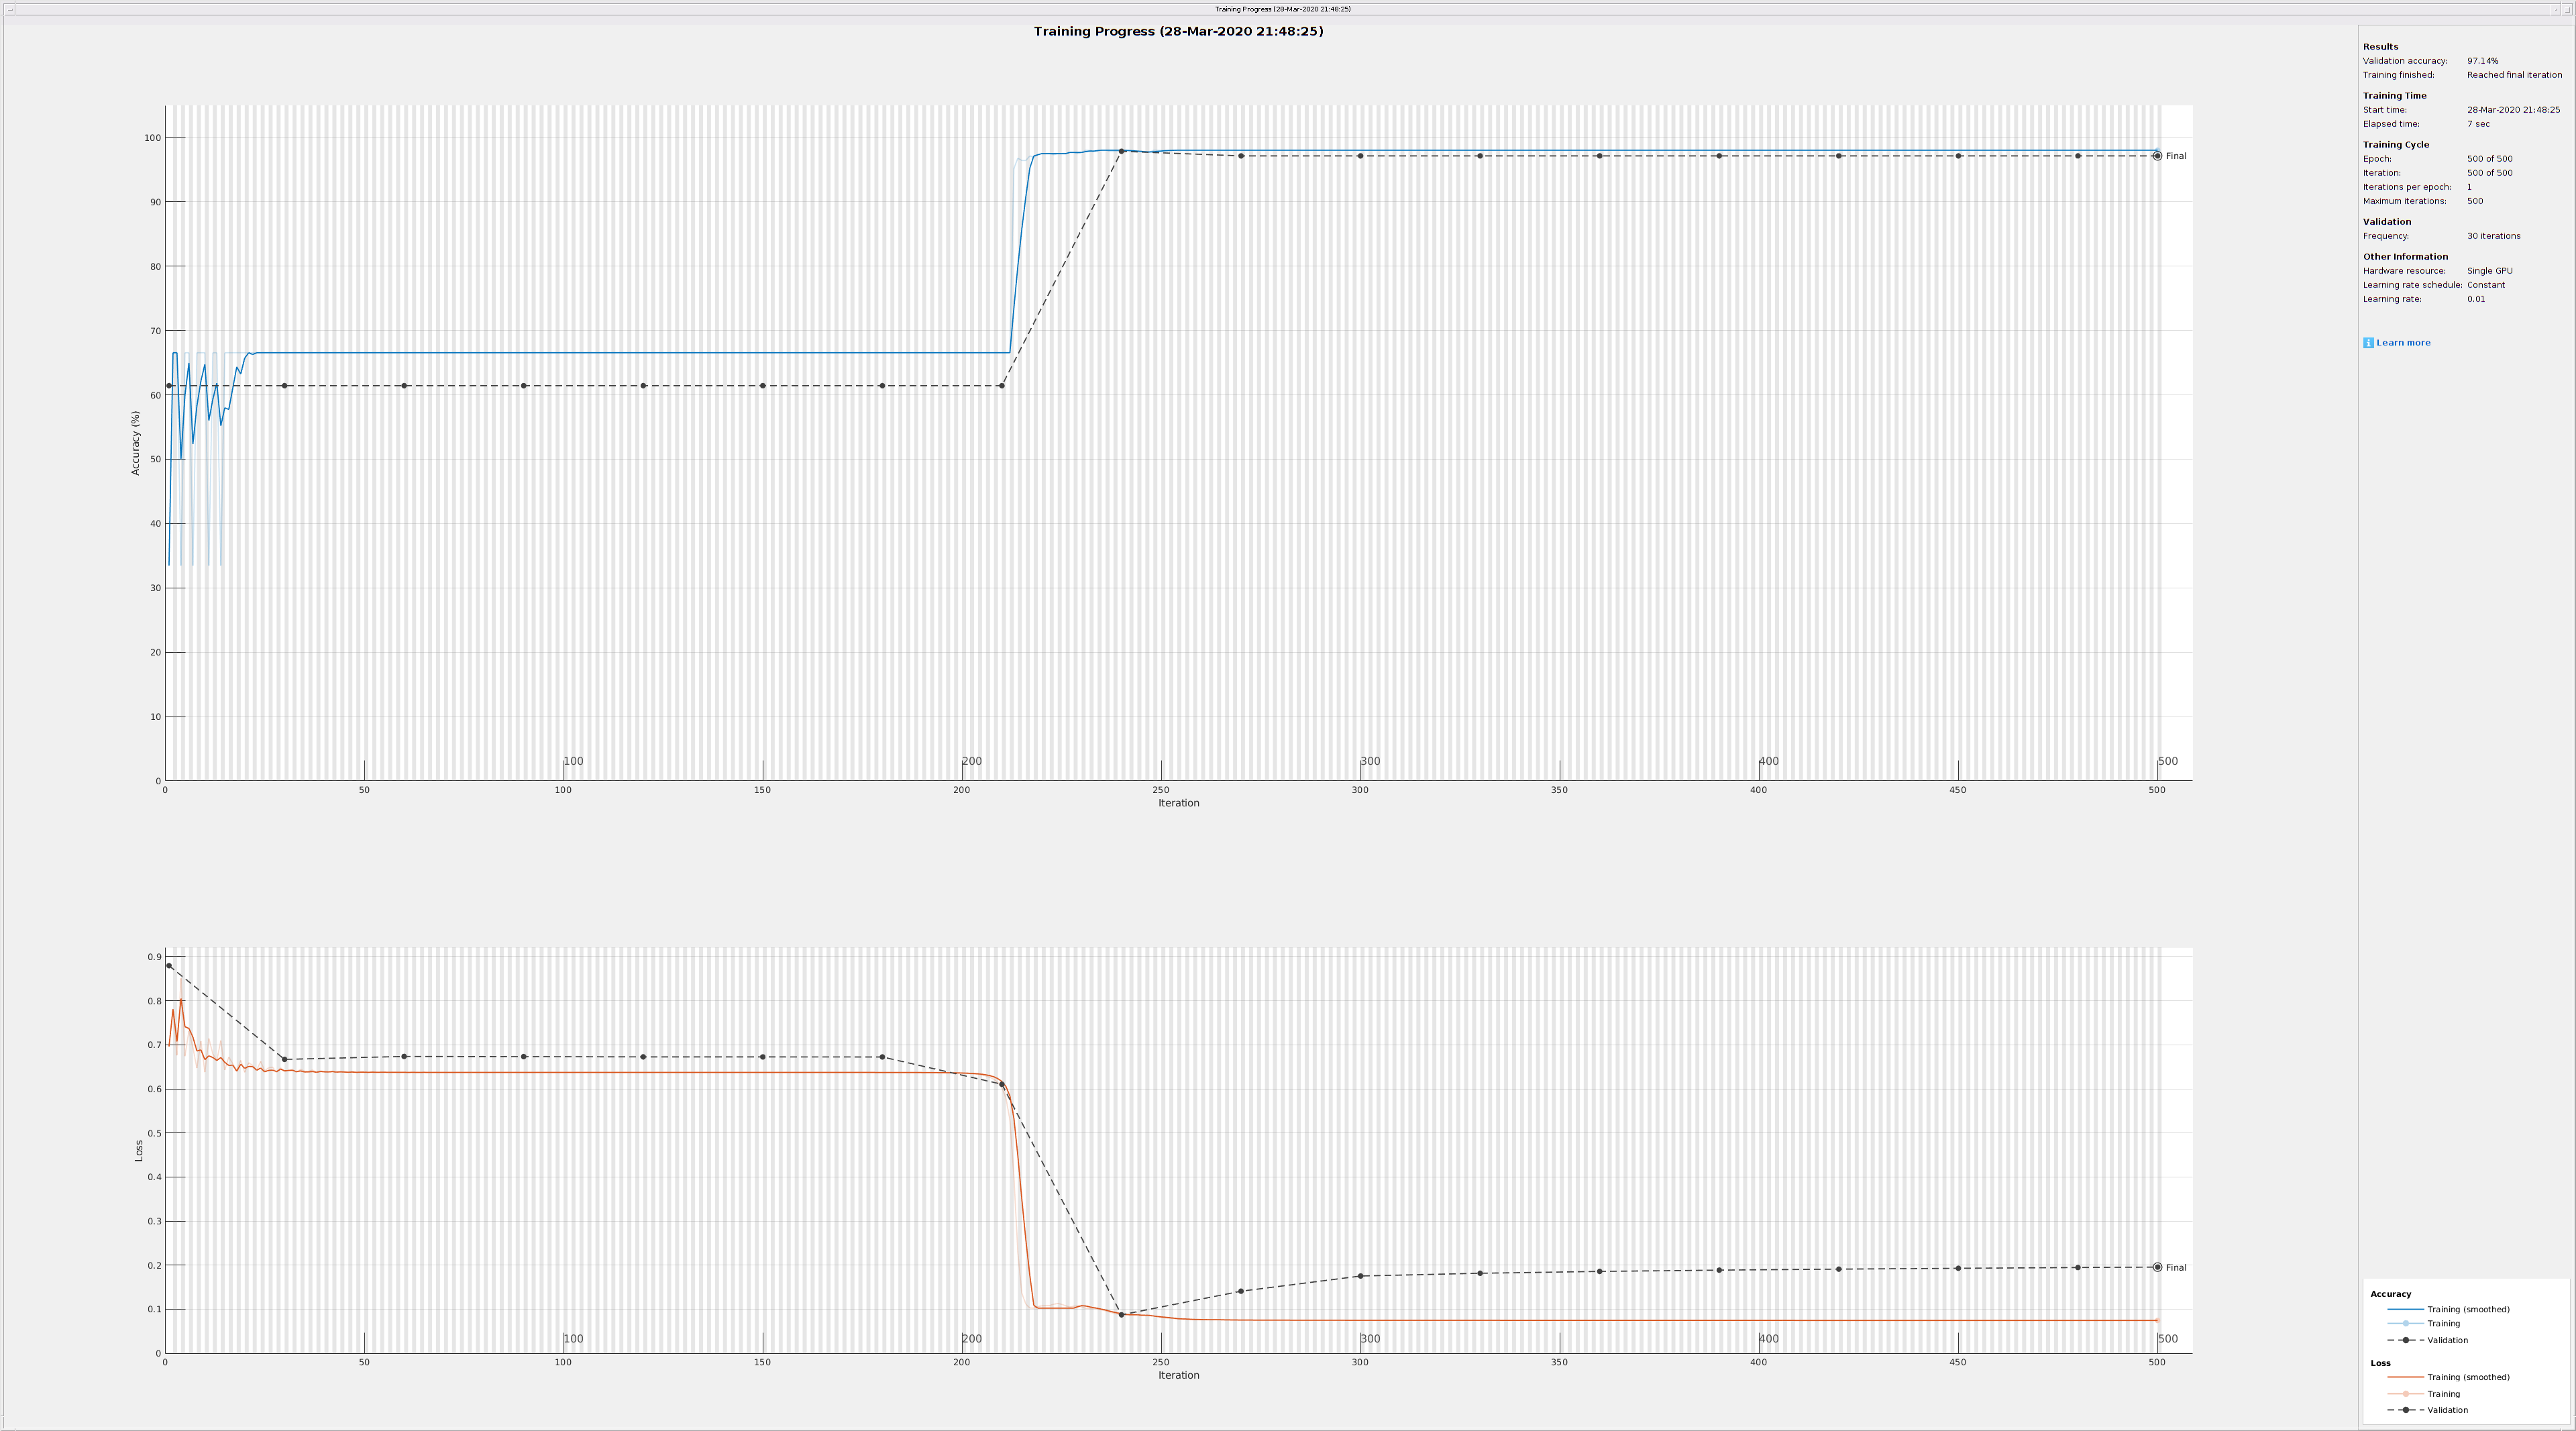

dnn =   SeriesNetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}


trainingInfo = struct with fields:
               TrainingLoss: [1×500 double]
           TrainingAccuracy: [1×500 double]
             ValidationLoss: [1×500 double]
         ValidationAccuracy: [1×500 double]
              BaseLearnRate: [1×500 double]
        FinalValidationLoss: 0.1956
    FinalValidationAccuracy: 97.1429


Ytrain = categorical(Ytrain); Ytest = categorical(Ytest);

Now, we need to specify the neural network architecture. We will store the network as an array called `layers`. There are 4 components we need to specify:

- **Input data layer**: the specific function differs on the data type inputed. For numerical data, the `sequenceInputLayer` is the appropriate function, which needs the number of features as the parameter.

- **Hidden layer architecture**: the specific architecture needed to design a feedforward neural network is the `fullyConnectedLayer`, which needs the number of activation nodes as the first parameter. The `WeightsInitializer` and `BiasInitializer` parameters tell the function how to initialize the parameters, using small random numbers from a normal distribution.

- **Activation function**: Between each `fullyConnectedLayer` is the activation function. The `softmaxLayer` is the activation function we will use.

- **Classification layer** (optional): The `classificationLayer` transforms the values to their predicted labels.

% Specify neural network architecture
layers = [...

ypred_dnn = 2×140 single matrix
    0.9490    0.9490    0.0000    0.9490    0.0000    0.0000    0.9490    0.9490    0.0000    0.0000    0.9490    0.9490    0.0000    0.9490    0.9490    0.0000    0.0000    0.9490    0.9490    0.0000    0.9490    0.9490    0.9490    0.0000    0.0000    0.0000    0.9490    0.0000    0.9490    0.9490    0.9490    0.0000    0.9490    0.0000    0.0000    0.9490    0.9490    0.0000    0.0000    0.0000    0.9490    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.9490    0.0000    0.9490
    0.0510    0.0510    1.0000    0.0510    1.0000    1.0000    0.0510    0.0510    1.0000    1.0000    0.0510    0.0510    1.0000    0.0510    0.0510    1.0000    1.0000    0.0510    0.0510    1.0000    0.0510    0.0510    0.0510    1.0000    1.0000    1.0000    0.0510    1.0000    0.0510    0.0510    0.0510    1.0000    0.0510    1.0000    1.0000    0.0510    0.0510    1.0000    1.0000    1.0000    0.0510    1.0000    1.0000    1.0000    1.0000    1.0000    1.0

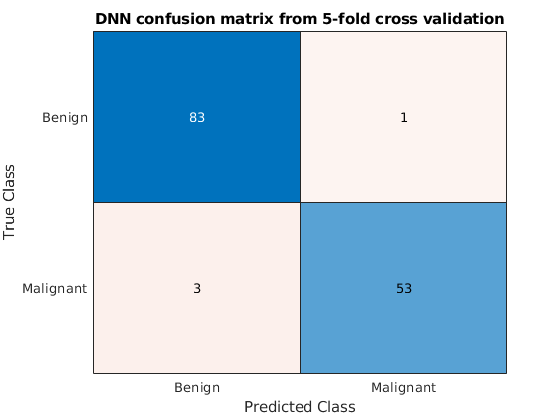

    
    sequenceInputLayer(size(Xtrain, 1)), ...            % Input data layer

    fullyConnectedLayer(10, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...

    'BiasInitializer', 'narrow-normal'), ...
    

malignant_precision = 0.9464

    softmaxLayer, ...                                   % Activation function 1

malignant_recall = 0.9815

benign_precision = 0.9651

    fullyConnectedLayer(40, ...                         % Hidden layer 2 with 40 nodes

benign_recall = 0.9881

    'WeightsInitializer', 'narrow-normal', ...

average_accuracy = 0.9714

    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 2
    
    fullyConnectedLayer(2, ...                          % Hidden layer 3 with 2 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 3
    
    classificationLayer ...                             % Label encode
]

Next, we have to specify the model hyperparameters. The `trainingOptions` function creates a model object that lets you feed in the hyperparameters into the neural network function. The specific arguments we will use are shown below.

% Spcify hyperparameters for neural network
options = trainingOptions(...
    'sgdm', ...                                   % Stochastic gradient descent
    'MaxEpochs', 500, ...                         % Maximum number of epochs to train algorithm
    'ValidationData', {Xtest, Ytest}, ...         % Dataset to use as the validation set
    'ValidationFrequency', 30, ...                % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress');                % Show plots for every epoch

Finally, let's train the neural network using the `trainNetwork` function, which allows us to train other deep neural network architectures, including convolutional neural networks (ConvNets) and long short-term memory (LSTM) networks. 

[dnn, trainingInfo] = trainNetwork(Xtrain, Ytrain, layers, options)

The plot shown in the popup shows the accuracy and cost of training the neural network as a function the number of epochs, and shows the generation of the accuracy / cost curves in real time. 

To make predictions using the deep neural network model, we can use the built-in `predict` function, which returns the class probabilites.

ypred_dnn = predict(dnn, Xtest)

Let's plot the final confusion matrix for the deep feedforward neural network:

cm = confusionmat(categorical(round(ypred_dnn(2, :))), Ytest);
figure; labels = {'Malignant', 'Benign'};
confusionchart(cm, labels)
title('DNN confusion matrix from 5-fold cross validation');
TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)
malignant_recall    = (TP) / (TP + FN)
benign_precision    = (TN) / (TN + FP)
benign_recall       = (TN) / (TN + FN)
average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

This 